## With my RK4

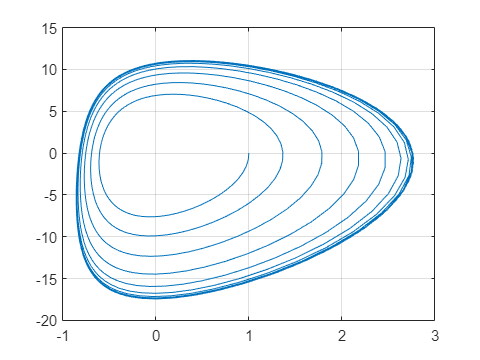

% Initial conditions (t=0)
global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.7;c2=0.4;al2=-437.5;bt2=0.003;

h=0.01;
ti=0; tf=10;
x0=1;y0=0;
N=ceil((tf-ti)/h);

t=zeros(1,N+1);
x=zeros(1,N+1);
y=zeros(1,N+1);

t(1)=ti;
x(1)=x0;
y(1)=y0;

[x,y] = RK4(t,tf,h,x,y);
plot(x,y)
grid on

## Using ode45

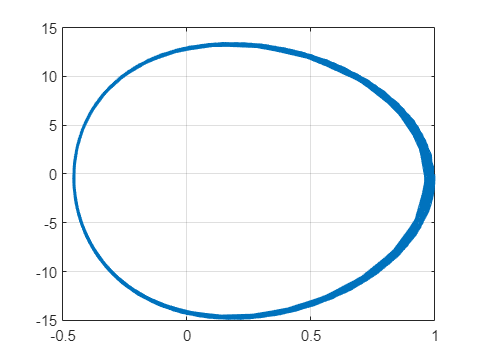

[T, XY]= ode45(@fQsys, [ti tf], [x0 y0]);
plot(XY(: ,1), XY(: ,2));
grid on

## Functions

function dz=fQsys(t, z)
    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    dz=zeros(2,1); % z=(z(1),z(2))=(x,y)
    
    dz(1)=(a1 * z(1)^2+ b1 * z(1)* z(2)+ c1 * z(2)^2+ al1 * z(1)+ bt1 * z(2));
    dz(2)=(a2 * z(1)^2+ b2 * z(1)* z(2)+ c2 * z(2)^2+ al2 * z(1)+ bt2 * z(2));
end

function [x,y] = RK4(t,tf,h,x,y)

    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    
    % ODE
    dxdt=@(t,x,y) a1*x^2 + b1*x*y + c1*y^2 + al1*x + bt1*y;
    dydt=@(t,x,y) a2*x^2 + b2*x*y + c2*y^2 + al2*x + bt2*y;
    
    % Step size
    N=ceil(tf/h);
    
    % Runge-Kutta 4
    
        for i=1:N
            t(i+1)=t(i)+h;
        
            k1x=dxdt(t(i), x(i), y(i));
            k1y=dydt(t(i), x(i), y(i));
        
            k2x=dxdt(t(i)+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
            k2y=dxdt(t(i)+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
        
            k3x=dxdt(t(i)+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
            k3y=dxdt(t(i)+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
        
            k4x=dxdt(t(i)+h, x(i)+h*k3x, y(i)+h*k3y);
            k4y=dxdt(t(i)+h, x(i)+h*k3x, y(i)+h*k3y);
        
            x(i+1)=x(i) + h/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + h/6*(k1y+2*k2y+2*k3y+k4y);
        end
end